## **This is a simulation of a toppling domino brick**

Dimensions of a domino brick in meters.

height = 5.08/100;
width = 2.54/100;
thickness = 0.9525/100;

The domino brick is made of hard plastic which has the density 940 kg /m3

mass = 11.553/1000;
g = 9.82;

distance between each brick

distance = 2/100;

Moment of inertia

J = mass*(height^2+thickness^2)/12;

Distance from point of impact on the brick to its pivot point.

d = sqrt(height^2+thickness^2);

Conditions for running the simulation

totalTime = 0.2;
s = 0.001;
samples = totalTime/s;
z = 1;

Several arrays for storing the data of the euler approximation of the derived differential equations. Angular acceleration, angular velocity and total traveled angle respectively. 

ang_acc = zeros(1,samples);
ang_vel = zeros(1,samples);
tot_ang = zeros(1,samples);
mg = zeros(1,samples);
retur = 0;

b = acos(distance/height);
collision_angle = (pi/2)-b;

Euler approximation

for i=0:s:totalTime-s
    if z== samples
        break
    end

total torque applied on the domino, the function proj_mass calculates the distance between the pivot point of the domino and its center of mass projected on the ground.

We save the values for the force of the gravity on the brick so we can add it to the following brick.

    mg(z) = mass*g*proj_mass(tot_ang(z),thickness,height,z);
    tao = impulse_force(i)*d + mg(z);

From the derived differential equations the angular acceleration, angular velocity and total angel is calculated.

    ang_acc(z+1) = tao/J;
    ang_vel(z+1) = ang_vel(z) + s * ang_acc(z);
    tot_ang(z+1) = tot_ang(z) + s * ang_vel(z);

    if tot_ang(z+1) >= pi/2
        tot_ang(z+1:samples) = pi/2;
        ang_acc(z+1) = 0;
        ang_vel(z+1) = 0;
        break
    end
    if abs(tot_ang(z)-collision_angle) < 0.01
        ang_vel(z+1) = 1;
        ang_acc(z+1) = 1;
    end
    if tot_ang(z+1) < 0
        tot_ang(z+1) = 0;
        ang_vel(z+1) = 0;
        ang_acc(z+1) =0;
        break
    end
    z = z + 1;
end
% writematrix(tot_ang, 'totalAngle.txt');

b is the angle which determines at what angle the bricks collide. k finds the total traveled angle of the initial brick before it collides with the next brick. 

b = acos(distance/height);
collision_angle = (pi/2)-b;
k = find(tot_ang < collision_angle, 1, 'last' );

x is the distance from the bottom of the brick to the point it gets hit by the brick before it.

r is the distance from the point of impact to the pivot point.

x = sin(b)*height;
r = sqrt(thickness^2+x^2);

Since we need the force to be perpendicular to the new brick the force from the previous brick is divided into its components. Fr is the force from the previous brick and F is the perpendicular force acting on the new brick. 

Fr = ang_acc(k)*J/height

Fr = 0.0216

Fx = Fr/cos(collision_angle)

Fx = 0.0235

ang_acc1 = zeros(1,samples);
ang_vel1 = zeros(1,samples);
tot_ang1 = zeros(1,samples);
mg1 = zeros(1,samples);
z = 1;
for i = 0:s:totalTime-s
    if z==samples
        break
    end
    tao = 0;

At the moment of collision between the bricks, the torque gained from the force of gravity acting on the initial brick is added to the new bricks total torque.

    if z >= k
        tao = newForce(i,Fx)*r + g*mass*proj_mass(tot_ang1(z), thickness, height, z);
        tao = tao + mg(z);
        mg1(z) = tao;
    end
    ang_acc1(z+1) = tao/J;
    ang_vel1(z+1) = ang_vel1(z)+ s * ang_acc1(z);
    tot_ang1(z+1) = tot_ang1(z) + s * ang_vel1(z);

    if tot_ang1(z+1) < 0
        tot_ang1(z+1:samples) = 0;
        ang_vel1(z+1) = 0;
        ang_acc1(z+1) =0;
        break
    end

    if tot_ang1(z+1) >= pi/2
        tot_ang1(z+1:samples) = pi/2;
        ang_acc1(z+1) = 0;
        ang_vel1(z+1) = 0;
        break
    end
    z = z + 1;
end

k = find(tot_ang1 < collision_angle, 1, 'last' );
Fr = ang_acc1(k)*J/height;
Fx = Fr/cos(collision_angle)

Fx = 0.0653

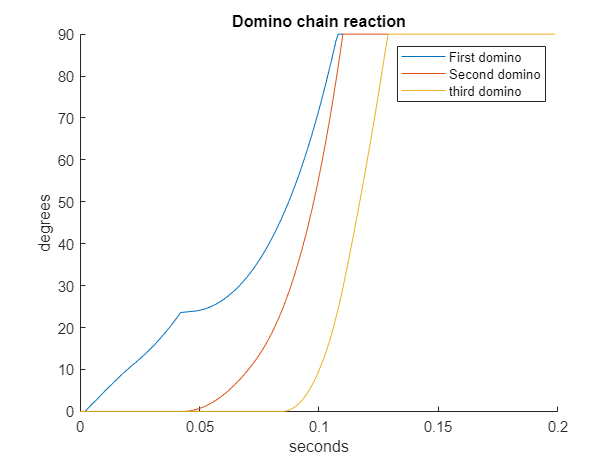


ang_acc2 = zeros(1,samples);
ang_vel2 = zeros(1,samples);
tot_ang2 = zeros(1,samples);
z = 1;

for i = 0:s:totalTime-s
    if z==samples
        break
    end

    tao = 0;
    if z >= k
        tao = newForce(i,Fx)*r + g*mass*proj_mass(tot_ang2(z), thickness, height, z);
        tao = tao + mg1(z);
    end
    ang_acc2(z+1) = tao/J;
    ang_vel2(z+1) = ang_vel2(z) + s * ang_acc2(z);
    tot_ang2(z+1) = tot_ang2(z)+ s * ang_vel2(z);

    if tot_ang2(z+1) < 0
        tot_ang2(z+1:samples) = 0;
        ang_vel2(z+1) = 0;
        ang_acc2(z+1) =0;
        break
    end

    if tot_ang2(z+1) >= pi/2
        tot_ang2(z+1:samples) = pi/2;
        ang_acc2(z+1) = 0;
        ang_vel2(z+1) = 0;
        break
    end
    z = z + 1;
end

t = 0:s:totalTime-s;
hold on
plot(t, rad2deg(tot_ang));
plot(t, rad2deg(tot_ang1));
plot(t, rad2deg(tot_ang2));
title('Domino chain reaction')
xlabel('seconds')
ylabel('degrees')
legend('First domino', 'Second domino', 'third domino');